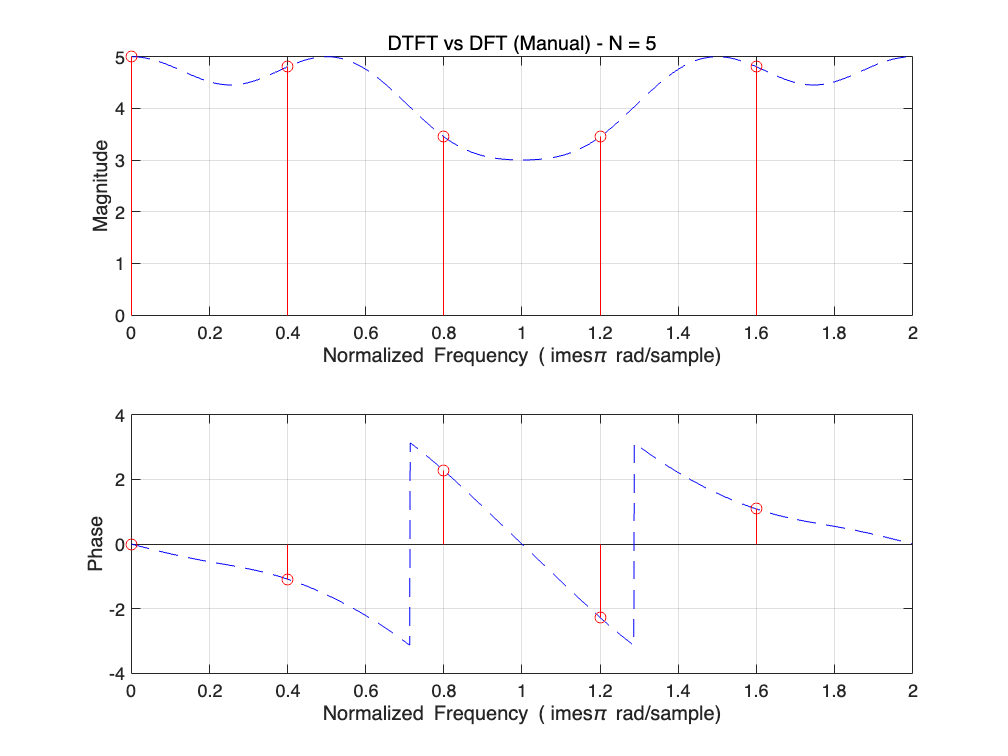


%% DSP Homework 


%% Problem1
clear; clc;
N = 5;
x_signal = [1 3 2 -2 1];
n = 0:4;

% DTFT
M = 1600;
omega = 2*pi * (0:M-1)/M;
X_dtft = x_signal * exp(-1j * n' * omega);

% DFT (Manual)
k = 0:N-1;
WN = exp(-1j * 2*pi/N);
X_dft_manual = x_signal * WN.^(n' * k);
x_idft_manual = 1/N * X_dft_manual * WN.^(-k' * n);
omega_dft = 2*pi * (0:N-1)/N;

% DFT (Using FFT Function)
X_dft_fft = fft(x_signal, N);
x_idft_fft = ifft(X_dft_fft, N);

% Plot Comparison
figure;
subplot(2,1,1)
plot(omega/pi, abs(X_dtft), 'b--')
hold on
stem(omega_dft/pi, abs(X_dft_manual), 'r')
grid on
xlim([0 2])
xlabel('Normalized Frequency (	imes\pi rad/sample)')
ylabel('Magnitude')
title('DTFT vs DFT (Manual) - N = 5')

subplot(2,1,2)
plot(omega/pi, angle(X_dtft), 'b--')
hold on
stem(omega_dft/pi, angle(X_dft_manual), 'r')
grid on
xlim([0 2])
xlabel('Normalized Frequency (	imes\pi rad/sample)')
ylabel('Phase')

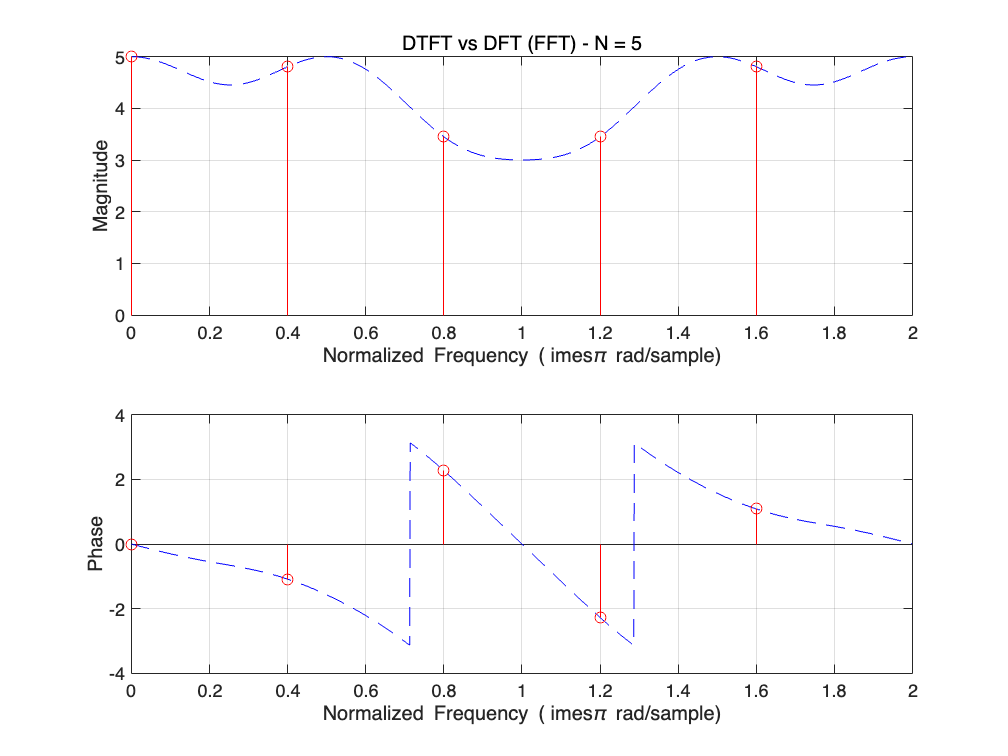


figure;
subplot(2,1,1)
plot(omega/pi, abs(X_dtft), 'b--')
hold on
stem(omega_dft/pi, abs(X_dft_fft), 'r')
grid on
xlim([0 2])
xlabel('Normalized Frequency (	imes\pi rad/sample)')
ylabel('Magnitude')
title('DTFT vs DFT (FFT) - N = 5')

subplot(2,1,2)
plot(omega/pi, angle(X_dtft), 'b--')
hold on
stem(omega_dft/pi, angle(X_dft_fft), 'r')
grid on
xlim([0 2])
xlabel('Normalized Frequency (	imes\pi rad/sample)')
ylabel('Phase')

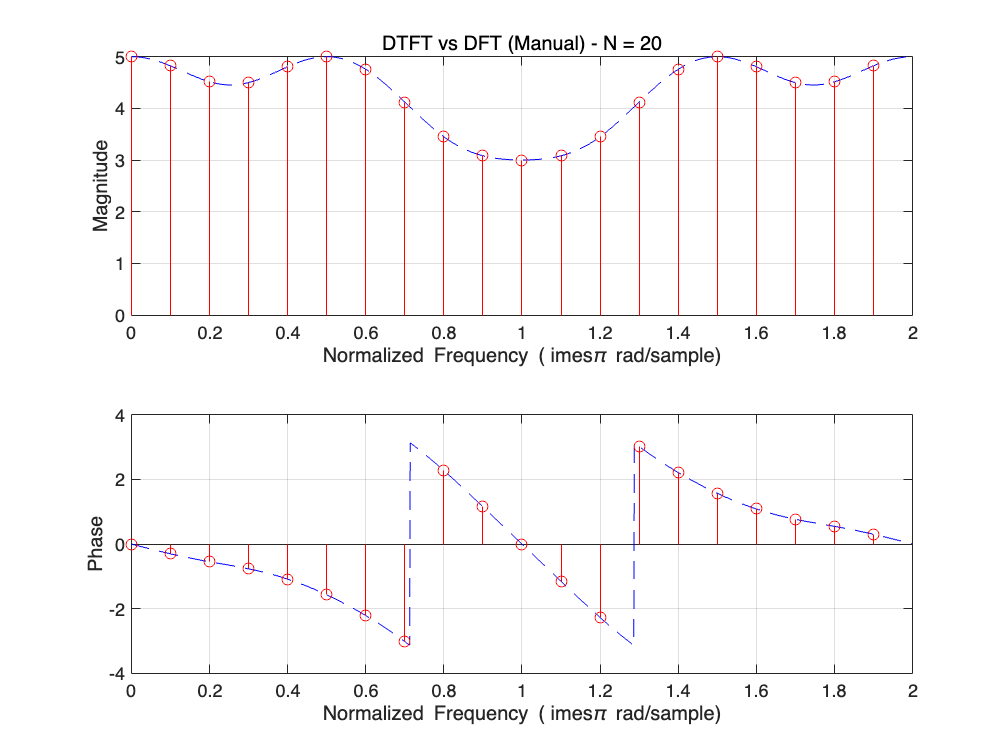


%% Problem2
clear;
N = 20;
x_orig = [1 3 2 -2 1];
x_padded = [x_orig zeros(1, N - length(x_orig))];
n = 0:N-1;

% DTFT
M = 1600;
omega = 2*pi * (0:M-1)/M;
X_dtft = x_orig * exp(-1j * (0:length(x_orig)-1)' * omega);

% DFT
k = 0:N-1;
WN = exp(-1j * 2*pi/N);
X_dft_manual = x_padded * WN.^(n' * k);
x_idft_manual = 1/N * X_dft_manual * WN.^(-k' * n);
omega_dft = 2*pi * (0:N-1)/N;

% FFT
X_dft_fft = fft(x_padded, N);
x_idft_fft = ifft(X_dft_fft, N);

% Plot Comparison
figure;
subplot(2,1,1)
plot(omega/pi, abs(X_dtft), 'b--')
hold on
stem(omega_dft/pi, abs(X_dft_manual), 'r')
grid on
xlim([0 2])
xlabel('Normalized Frequency (	imes\pi rad/sample)')
ylabel('Magnitude')
title('DTFT vs DFT (Manual) - N = 20')

subplot(2,1,2)
plot(omega/pi, angle(X_dtft), 'b--')
hold on
stem(omega_dft/pi, angle(X_dft_manual), 'r')
grid on
xlim([0 2])
xlabel('Normalized Frequency (	imes\pi rad/sample)')
ylabel('Phase')

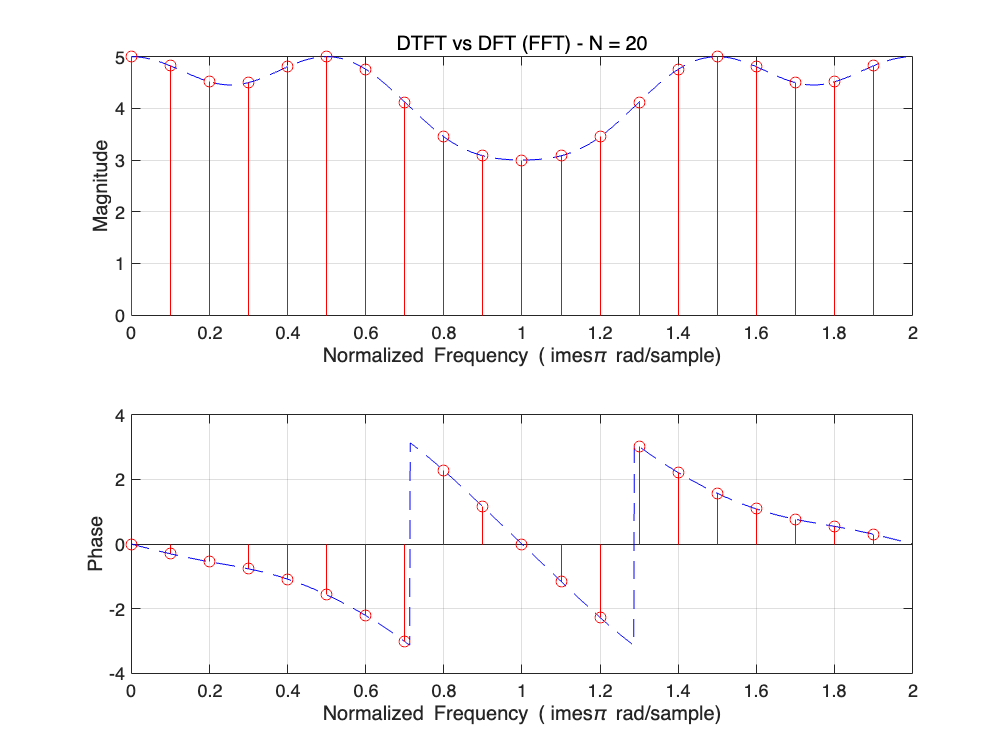


figure;
subplot(2,1,1)
plot(omega/pi, abs(X_dtft), 'b--')
hold on
stem(omega_dft/pi, abs(X_dft_fft), 'r')
grid on
xlim([0 2])
xlabel('Normalized Frequency (	imes\pi rad/sample)')
ylabel('Magnitude')
title('DTFT vs DFT (FFT) - N = 20')

subplot(2,1,2)
plot(omega/pi, angle(X_dtft), 'b--')
hold on
stem(omega_dft/pi, angle(X_dft_fft), 'r')
grid on
xlim([0 2])
xlabel('Normalized Frequency (	imes\pi rad/sample)')
ylabel('Phase')

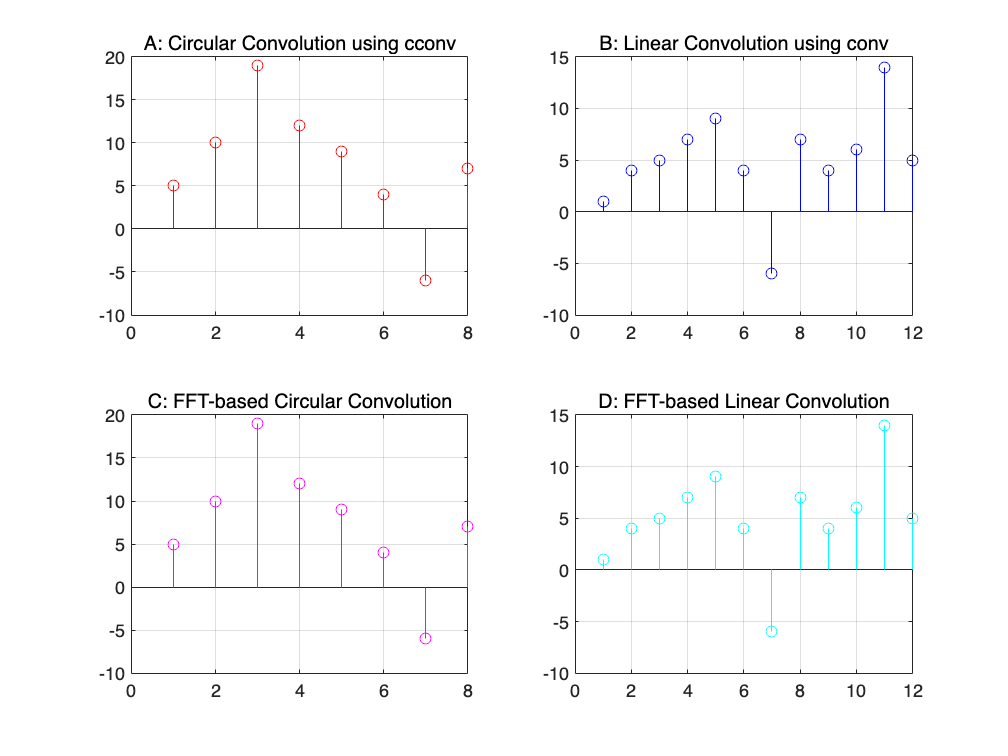


%% Problem3
clear;
x = [1, 2, 3, 4, 5];
h = [1, 2, -2, 1, 0, -1, 2, 1];
N = 8;

% A: Circular Convolution (cconv)
y_circular = cconv(x, h, N);

% B: Linear Convolution (conv)
y_linear = conv(x, h);

% C: FFT-based Circular Convolution
X_fft = fft(x, N);
H_fft = fft(h, N);
Y_circular_fft = X_fft .* H_fft;
y_circular_fft = ifft(Y_circular_fft);

% D: FFT-based Linear Convolution
N_total = length(x) + length(h) - 1;
X_fft_linear = fft(x, N_total);
H_fft_linear = fft(h, N_total);
Y_linear_fft = X_fft_linear .* H_fft_linear;
y_linear_fft = ifft(Y_linear_fft);

% Plot Results
figure;
subplot(2,2,1)
stem(y_circular, 'r')
title('A: Circular Convolution using cconv')
grid on

subplot(2,2,2)
stem(y_linear, 'b')
title('B: Linear Convolution using conv')
grid on

subplot(2,2,3)
stem(real(y_circular_fft), 'm')
title('C: FFT-based Circular Convolution')
grid on

subplot(2,2,4)
stem(real(y_linear_fft), 'c')
title('D: FFT-based Linear Convolution')
grid on